# 5. Heat Transfer -thermalIC

[`thermalIC(thermalmodel,T0)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalic.html#d120e94075)`：`将初始温度或温度的初始猜测值设置为整个几何形状。

[`thermalIC(thermalmodel,T0,RegionType,RegionID)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalic.html#d120e94093)`：`将初始温度或温度的初始猜测值设置为特定的几何区域。

[`thermalIC(thermalmodel,Tresults)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalic.html#d120e94115)`：`Use Tresults’ previous thermal analysis of the same geometry and grid to set the initial temperature or initial temperature guess. If Tresults is obtained by solving transient thermal problems, thermalIC uses the solution Tresults for the last time step.

[`thermalIC(thermalmodel,Tresults,iT)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalic.html#d120e94139)`：`sets initial temperature or initial guess for temperature using the solution for the time-step from a previous thermal analysis on the same geometry and mesh.

[`thermalIC = thermalIC(``___``)`](https://ww2.mathworks.cn/help/pde/ug/pde.thermalmodel.thermalic.html#d120e94161)对于任何先前的语法，均返回热初始条件对象的句柄。

5.1 初始恒定温度：

Create a thermal model, import geometry, and set the initial temperature to 0 on the entire geometry.

% thermalModel = createpde('thermal','transient');
% aa=geometryFromEdges(thermalModel,@lshapeg);
% thermalIC(thermalModel,0)
% pdegplot(aa,"FaceLabels","on")

5.2 为子域设置初始温度

% thermalModel = createpde('thermal','transient');
% geometryFromEdges(thermalModel,@lshapeg);
% pdegplot(thermalModel,'FaceLabels','on')
% axis equal
% ylim([-1.1 1.1])

设置IC

% thermalIC(thermalModel,0,'Face',1)
% thermalIC(thermalModel,10,'Face',2)
% thermalIC(thermalModel,75,'Face',3)

5.3 非恒定初始温度

% thermalmodel = createpde('thermal','transient');
% g = decsg([3 4 -1.5 1.5 1.5 -1.5 0 0 .2 .2]');
% geometryFromEdges(thermalmodel,g);

Set the initial temperature in the rod to be dependent on the *y*-coordinate, for example, 10^3(0.2−y^2).

% T0 = @(location)10^3*(0.2 - location.y.^2);
% thermalIC(thermalmodel,T0)

5.4**Initial Condition as Previously Obtained Solution**

**创建一个正方形：**

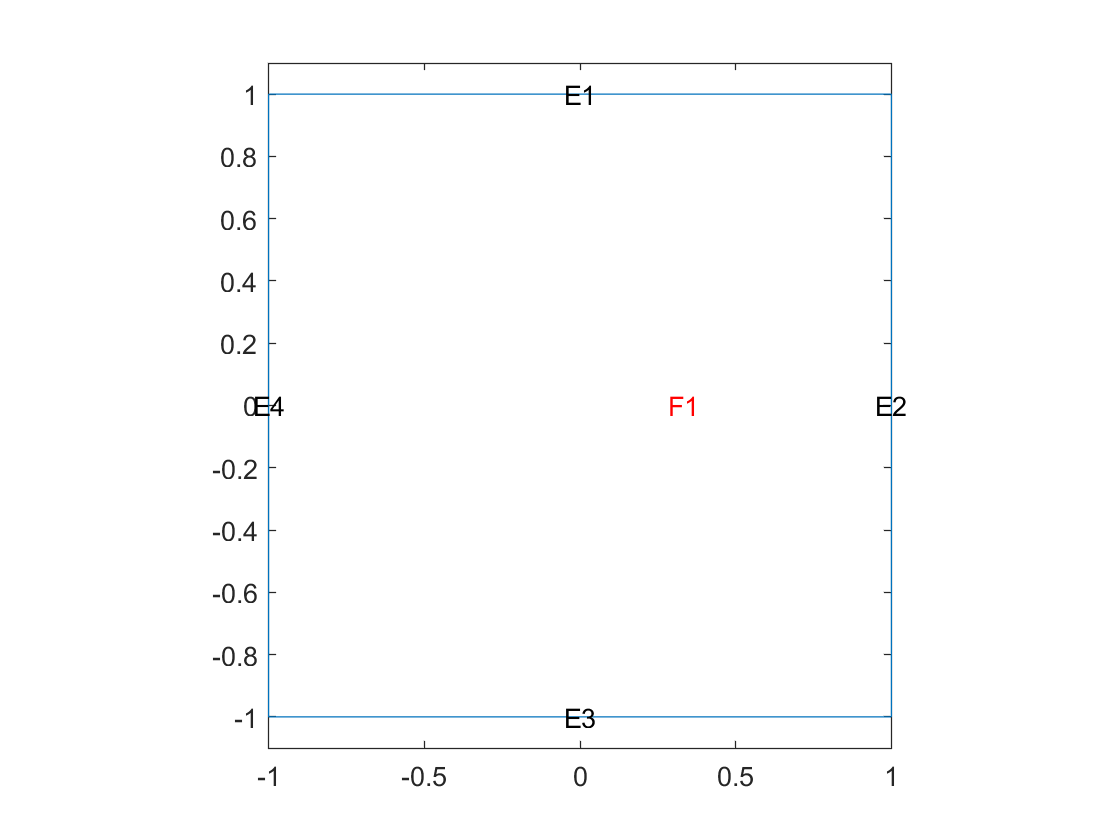

thermalmodel = createpde('thermal','transient');
geometryFromEdges(thermalmodel,@squareg);
pdegplot(thermalmodel,'FaceLabels','on',"EdgeLabels","on")
ylim([-1.1,1.1])
axis equal

Specify material properties and internal heat source, and set boundary conditions and initial conditions.

thermalProperties(thermalmodel,'ThermalConductivity',500,...
                               'MassDensity',200,...
                               'SpecificHeat',100);

internalHeatSource(thermalmodel,2);
thermalBC(thermalmodel,'Edge',[1,3],'Temperature',100);
thermalIC(thermalmodel,0);

Generate mesh, solve the problem, and plot the solution.

generateMesh(thermalmodel);
tlist = 0:0.5:10;
result1 = solve(thermalmodel,tlist)

result1 =   TransientThermalResults - 属性:

      Temperature: [1541×21 double]
    SolutionTimes: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10]
       XGradients: [1541×21 double]
       YGradients: [1541×21 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]


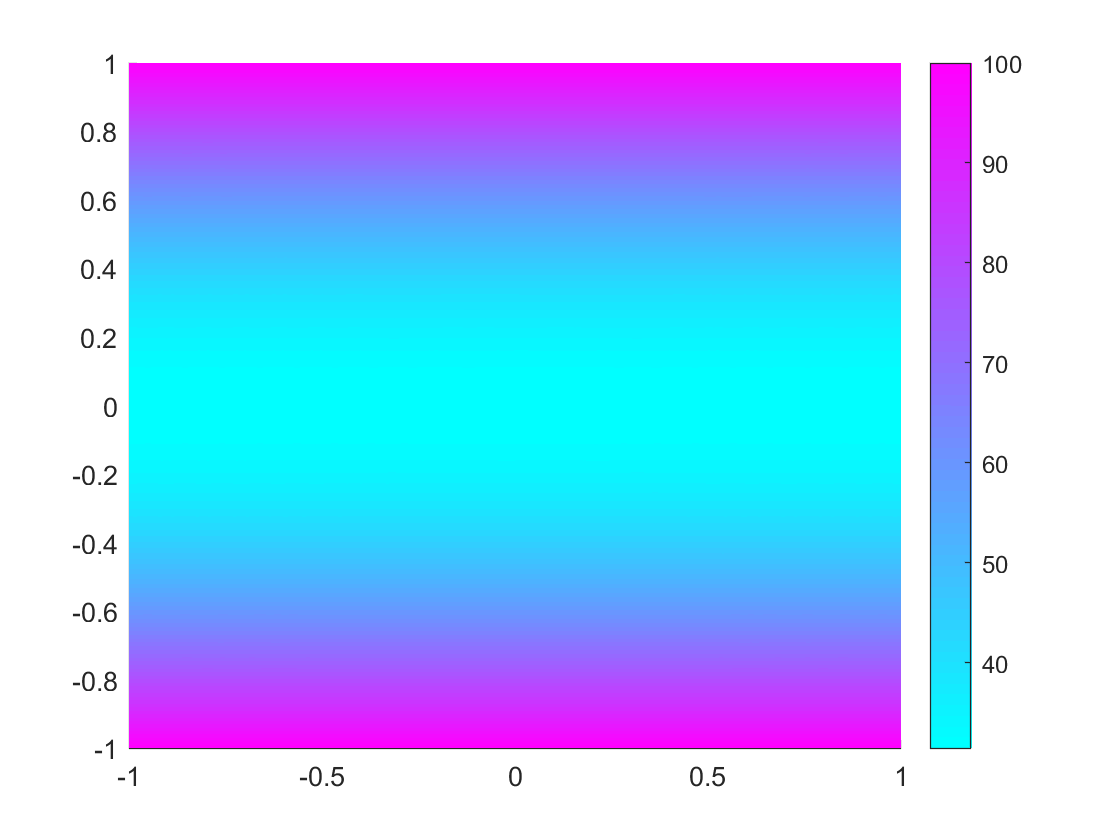

pdeplot(thermalmodel,'XYData',result1.Temperature(:,end))

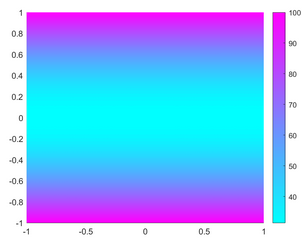

Now, resume the analysis and solve the problem for times from 10 to 15 seconds. Use the previously obtained solution for 10 seconds as an initial condition. Since 10 seconds is the last element in `tlist`, you do not need to specify the solution time index. By default, `thermalIC` uses the last solution index.

thermalIC(thermalmodel,result1)

ans =   NodalThermalICs - 属性:

    InitialTemperature: [1541×1 double]


result2 = solve(thermalmodel,10:0.5:15)

result2 =   TransientThermalResults - 属性:

      Temperature: [1541×11 double]
    SolutionTimes: [10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15]
       XGradients: [1541×11 double]
       YGradients: [1541×11 double]
       ZGradients: []
             Mesh: [1×1 FEMesh]


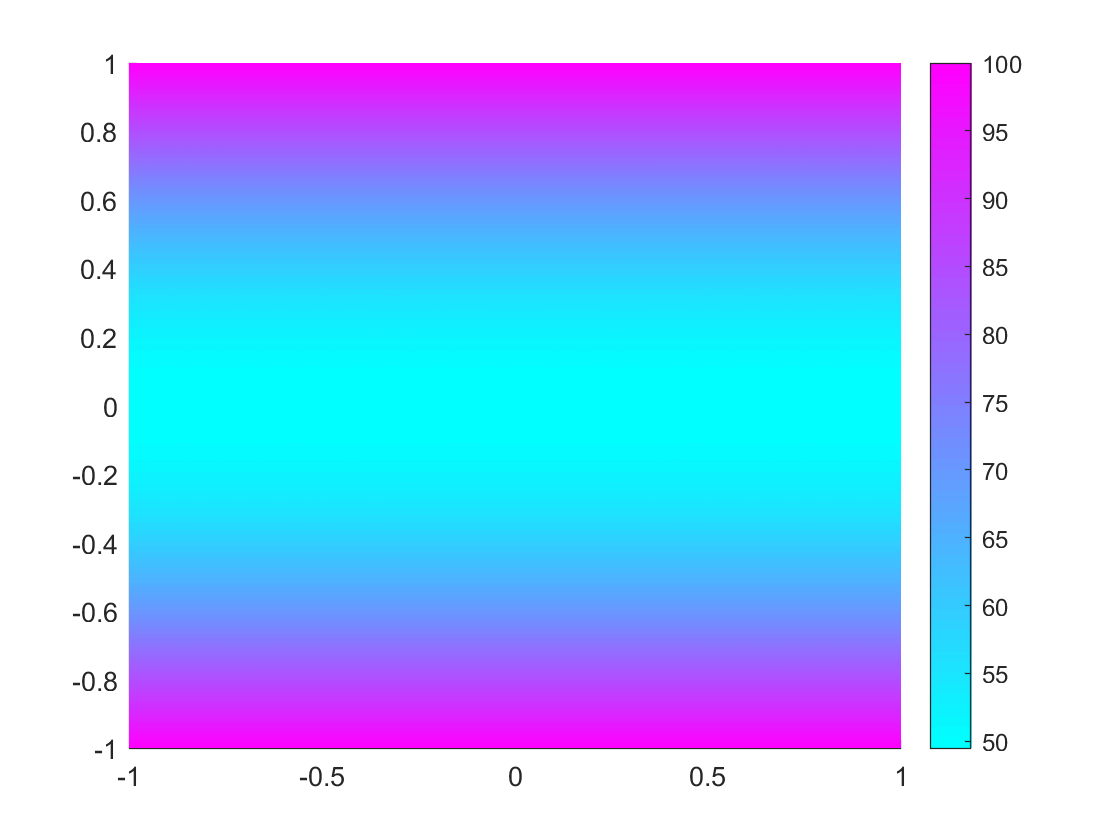

pdeplot(thermalmodel,'XYData',result2.Temperature(:,end))